# Motor Test Results and Analysis

Date: 2023-08-16

Author: Jonas Wagner

Test done with a motor that is believed to be damaged/not in optimal conditions

Data ingested from 20230815_224137_1.mp4 using dataIngest.m

clear
close all
T = readtable("data\motorTestData_20230815_224137_1.csv","VariableNamingRule","preserve");
T = fillmissing(T,"nearest");
T.omega = (2*pi/60).*T.RPM;
T.P_in_W = T.("Voltage (V)") .* T.("Current (A)");
T.P_out_W = T.("Torque (Nm)") .* T.omega;
T.eta = T.P_out_W ./ T.P_in_W

T = 2813×9 table
    Time (s)    Current (A)    Voltage (V)    Torque (Nm)    RPM    omega     P_in_W    P_out_W      eta   
    ________    ___________    ___________    ___________    ___    ______    ______    _______    ________

     1.6996         0.61          24.69           0.2         0          0    15.061          0           0
     1.7329        0.631          24.69           0.2         0          0    15.579          0           0
     1.7662         0.63          24.69           0.2         0          0    15.555          0           0
     1.7996         0.63         24.869           0.2         0          0    15.667          0           0
     1.8329         0.63    

% Energy (J) = Power (W) * Time (s)
E_total_in = sum(10*T.P_in_W);
E_total_out = sum(10*T.P_out_W);
eta_total = E_total_out/E_total_in;
fprintf('Total Energy In: %0d W\n',round(E_total_in)); fprintf('Total Energy Out: %0d W\n',round(E_total_out)); fprintf('Total Efficiency: %.2f%%',100*eta_total)

Total Energy In: 435145 W
Total Energy Out: 16355 W
Total Efficiency: 3.76%

## Plots

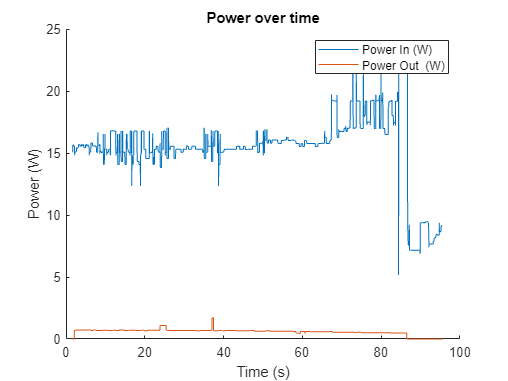

figure
hold on
plot(T.("Time (s)"), T.P_in_W, DisplayName = "Power In (W)")
plot(T.("Time (s)"), T.P_out_W, DisplayName = "Power Out  (W)")
title('Power over time')
xlabel('Time (s)')
ylabel('Power (W)')
legend

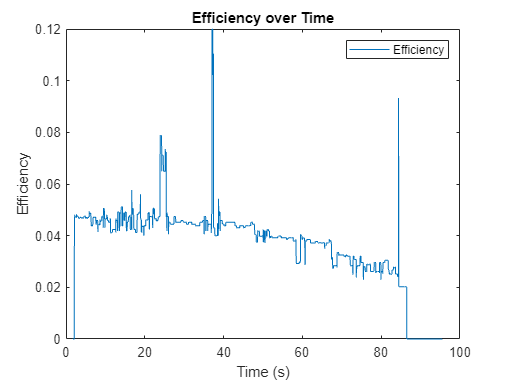


figure
plot(T.("Time (s)"), T.eta, DisplayName="Efficiency")
title('Efficiency over Time')
xlabel('Time (s)')
ylabel('Efficiency')
legend